# Capacitors: fundamentals

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

In this script, we will explore the fundamental properties and applications of capacitors using electrostatics principles. 

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB. Part of this script include Simscape simulations, no prior knowledge is assumed here, but you might want to consider taking [Simscape Onramp](https://matlabacademy.mathworks.com/details/simscape-onramp/simscape) as well.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Review of known concepts

### Capacitor fundamentals

Before diving into the functioning principles of a capacitor and how they relate to an electrical field, we should take a little time to reflect on what we already know about capacitors. In a previous course, you may have already learned that capacitors are passive components symbolized by the following diagram:

 **Reflect**. Are you feeling comfortable with the capacitor concept we discussed in this section? If not, you should probably refresh your knowledge of RC circuits using your resources, or explore our [RC circuit analysis courseware](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/DC-Circuit-Analysis&project=DCCircuitAnalysis.prj&file=Scripts/RCCircuits.mlx).

### Simulation and questioning

Alright! At this point, we should be pretty comfortable looking at an RC circuit. 

Remember its diagram? Well, that diagram is a fair representation of what a capacitor is! A capacitor is built out of two plates separated by a small gap filled with air (or most likely a dielectric material, but we'll come to that later).

 **Exercise 1. **If a capacitor is two plates separated by an air gap, it should behave as a(n) _______. (Complete the sentence with the live control below)

CheckExercise1("Select")

function CheckExercise1(Answer)
switch Answer
    case "Select"
        warning("Please select a valid answer.")
    case "Conductor"
        warning("Because of the air gap, the capacitor should act as an insulator.")
    case "Insulator"
        disp("Right! Because of the air gap, the capacitor should act as an insulator.")
end
end

We prepared a small simulation of an RC circuit using Simscape. We have a resistor and a capacitor in series with a voltage source that will switch from an imposed voltage of 0 V to 1 V after 1 second of simulation. The total simulation time is 10 seconds.

  **Try**. Open the `SimpleRC.slx` model. The Signal Editor block controls the two switches in the model. Open this block dialog box to visualize the signal controlling the switches.

function OpenSimpleRC(ActiveScenario)
arguments
    ActiveScenario (1,1) string = "SimpleCharge"
end
    Model = fullfile("Models","SimpleRC.slx");
    open_system(Model)
    Block = find_system("SimpleRC/Signal Editor");
    set_param(Block{1},"ActiveScenario",ActiveScenario);
end

OpenSimpleRC
 

 **Exercise 2.  **Now that you are familiar with the circuit that we are studying. In the **Signal Edito**r block, select `SimpleCharge` as the active scenario. Run the simulation and then click the button below to visualize the result.

 
if exist("out","var")
    plot(out.SimlogSimpleRC.Capacitor.i);
    title("Capacitor")
    ylabel("Current (A)")
    xlabel("Time (s)")
    ylim("padded")
    xlim([0 3])
    grid off
else
    warning('Run the simulation in the SimpleRC.slx Simscape model if you want to visualize the results. Reopen and run the simulation ')
end

 **Pro-tip. **You could also use the Simscape Results Explorer from the Simulink toolstrip to check the capacitor's current.

Based on what you are observing with the simulation...

CheckExercise2("Select")

function CheckExercise2(Answer)
switch Answer
    case "Select"
        warning("Please select a valid answer.")
    case "Conductor"
        warning("How could it be a conductor when, at steady-state, the current is zero despite behind connected to a perfect voltage source.")
    case "Insulator"
        warning("How could it be an insulator, it clearly carries current he switch closes.")
    case "BothNeither"
        disp("Right! It appears that capacitor diplay a conductor behavior during the transient regime when the switch closes, and insulator behavior at steady-state.")
end
end

 **Reflect**. How does a capacitor display dual behavior as both a capacitor and an insulator?

## **What would Gauss think of capacitors?**

### **Computing the electric field**

We know that a capacitor is formed with two surfaces of conductive material separated by a thin gap. There are a variety of geometries and materials used to create the capacitors that we use in everyday electronics:

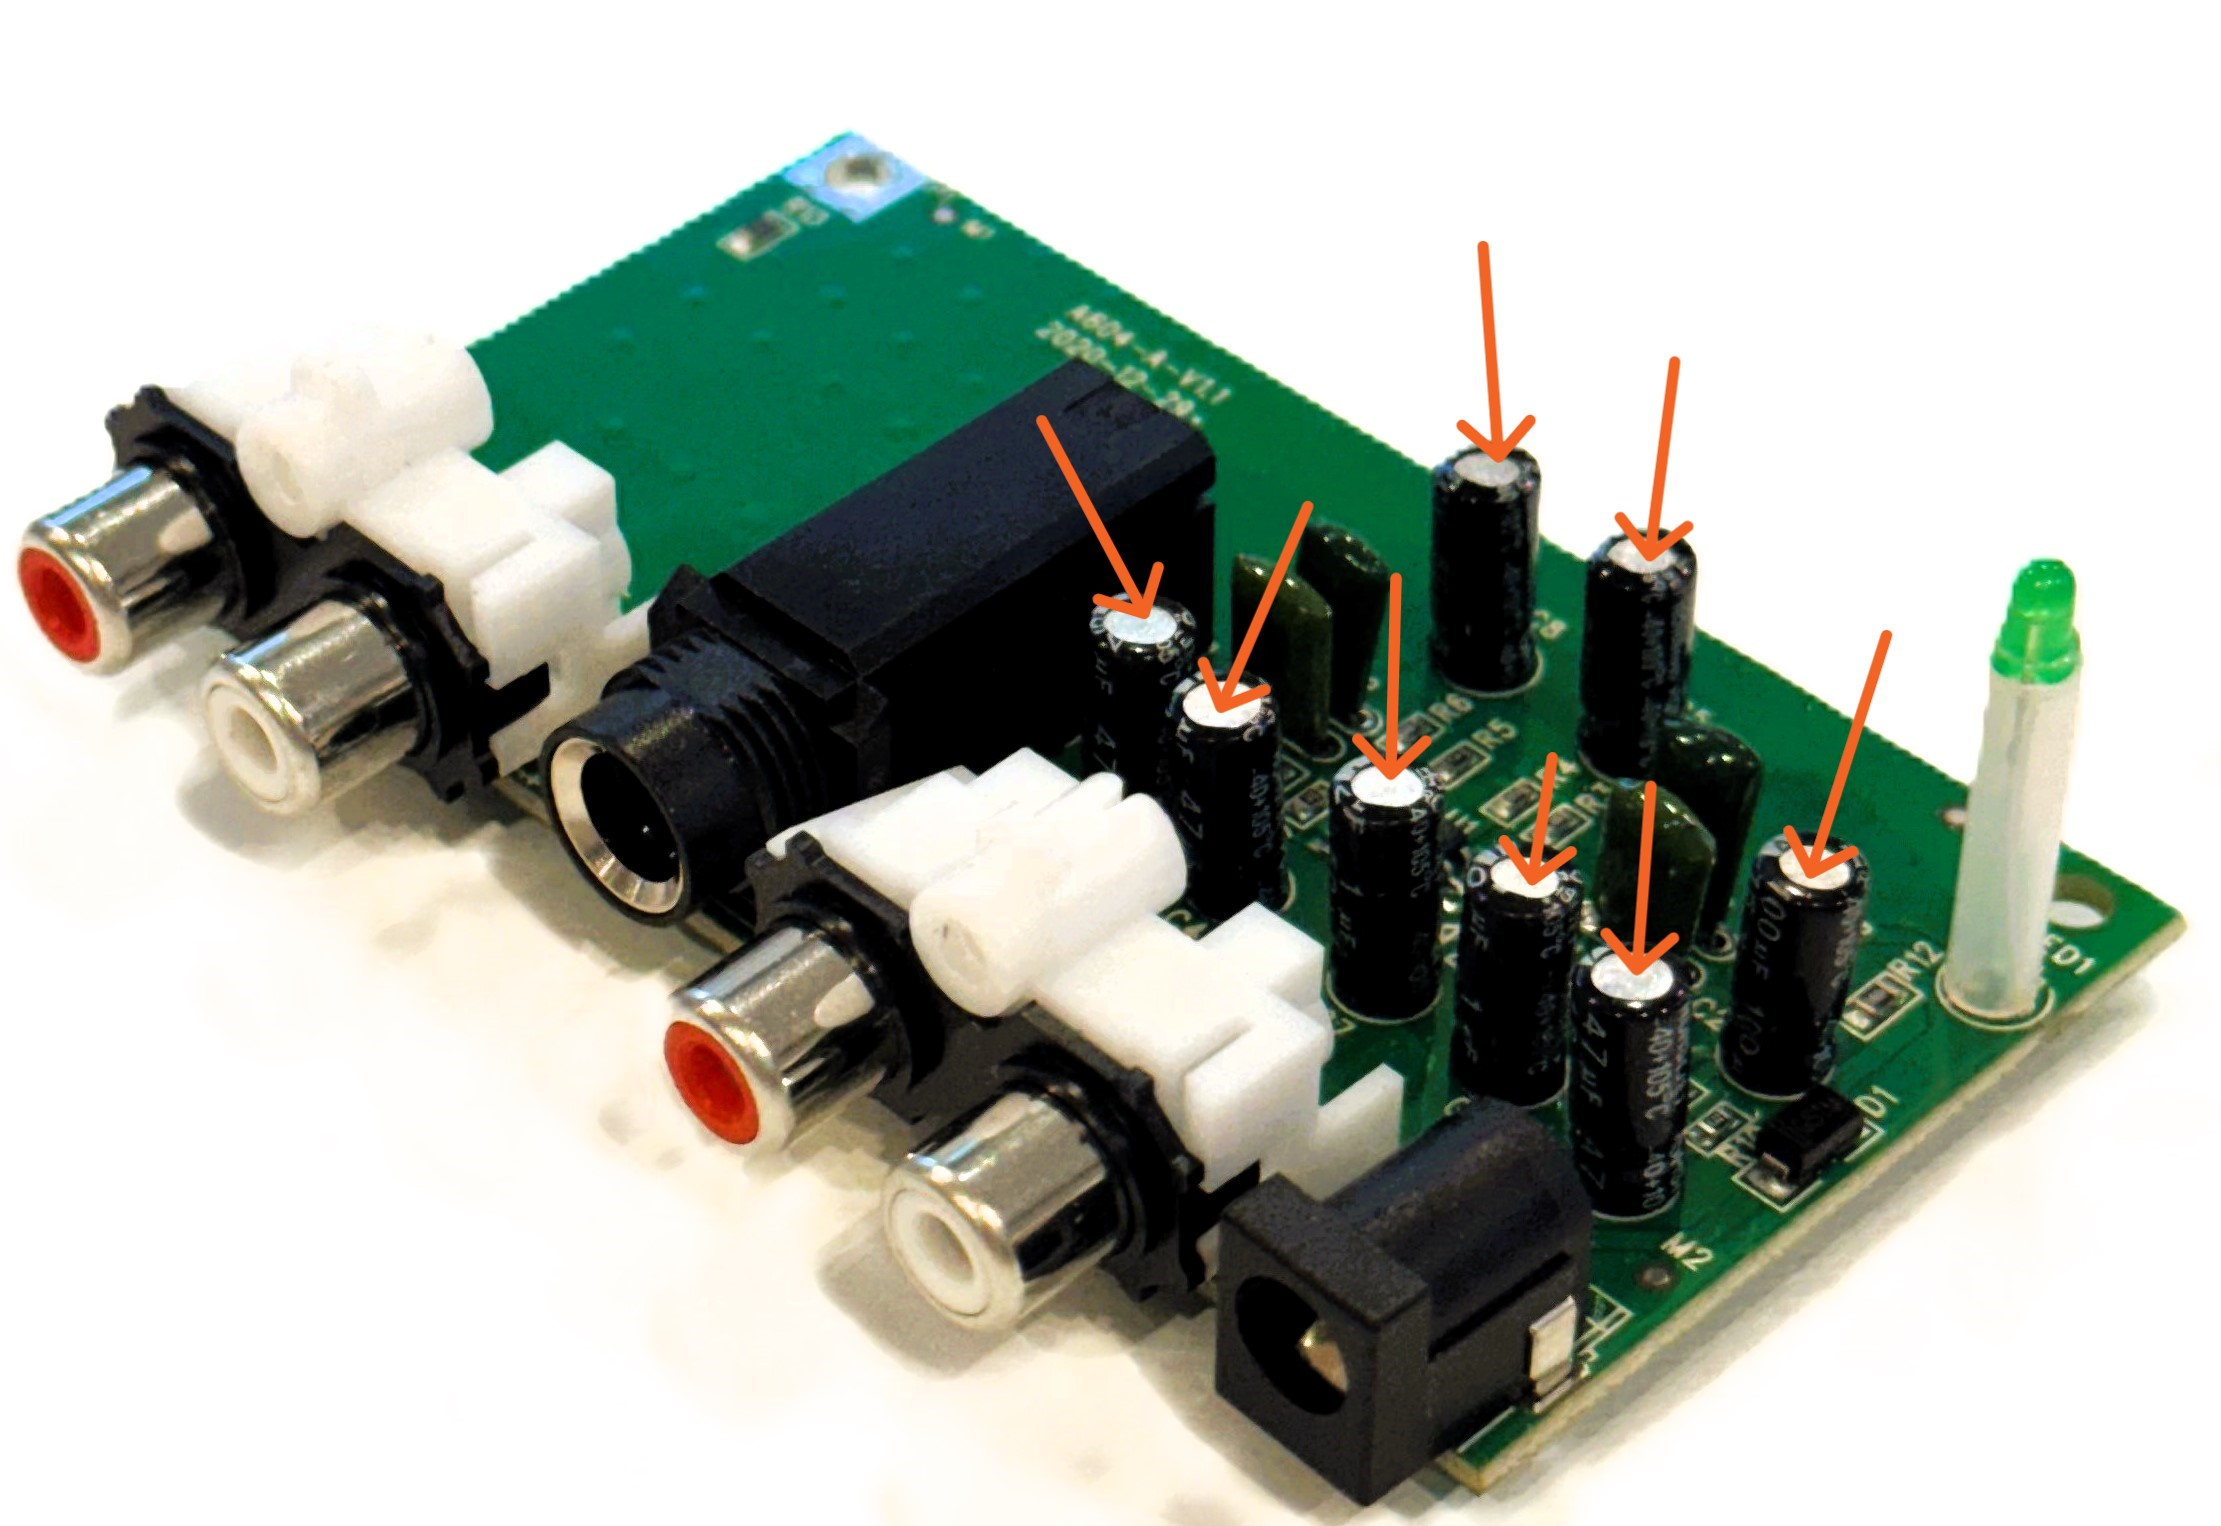

A picture of an audio preamplifier board with some capacitors is highlighted.

We can create an idealized capacitor using an elementary geometry. One of the simplest geometries is two infinitely long conductive plates separated by a distance gap $d$. We learned from Gauss that an infinite plate with charge density $\sigma$ would generate an electric field ($\bf{E}$) outside the surface. The magnitude of the electric field is:


$$E = \frac{\sigma}{2\varepsilon_0}$$


where $\varepsilon_0$ is the permittivity of free space. The electric field is oriented perpendicular to the charged plane. We shall call this an infinite plate capacitor.

  **Try.** Visualize the orientation of the electric field generated by a single infinite plate depending on the charge's sign.

 

figure
yline(0,SeriesIndex="none",LineWidth=3,DisplayName="$\sigma$",Alpha=1)
hold on
if "Positive" == "Positive"  
    quiver([1 2 3 1 2 3],[1 1 1 -1 -1 -1],[0 0 0 0 0 0],[1 1 1 -1 -1 -1],'off',DisplayName="$\vec{E}$",SeriesIndex=1)
else
    quiver([1 2 3 1 2 3],[2 2 2 -2 -2 -2],[0 0 0 0 0 0],[-1 -1 -1 1 1 1],'off',DisplayName="$\vec{E}$",SeriesIndex=2)
end
ylim([-2.5 2.5])
hold off
axis off
legend(Interpreter="latex",Location="bestoutside")

As we are charging the capacitor, positive charge will accumulate on the positive plate (top), and negative charge will accumulate on the negative plate (bottom).

In the simulation, we imposed a current on the capacitor, charging the top plate with positive charges and the bottom plate with negative charges. We are denoting the positive charge density $\sigma^+$ and the negative charge density $\sigma^-$ with $\sigma = |\sigma^+| = |\sigma^-|$. We can use the superposition principle to compute the total electric field generated by the two plates of the capacitor.

  **Try.** Use the live control below to visualize the components of the electric field for the infinite plate capacitor.

VisualizeCapacitorField([false false],...
    "None")
 


function VisualizeCapacitorField(Show,Highlight)
    figure
    yline(1,SeriesIndex=1,LineWidth=3,DisplayName="$\sigma^+$",Alpha=1)
    yline(-1,SeriesIndex=2,LineWidth=3,DisplayName="$\sigma^-$",Alpha=1)
    hold on
    FieldFromTop = quiver([1 2 3 1 2 3 1 2 3 ],...
        [1.4 1.4 1.4 0.6 0.6 0.6 -1.4 -1.4 -1.4],...
        [0 0 0 0 0 0 0 0 0],...
        [1.2 1.2 1.2 -1.2 -1.2 -1.2 -1.2 -1.2 -1.2],...
        'off',SeriesIndex="none",DisplayName="Field from top plate",LineWidth=2);
    FieldFromBottom = quiver([1 2 3 1 2 3 1 2 3]+0.2,...
        [2.6 2.6 2.6 0.6 0.6 0.6 -2.6 -2.6 -2.6],...
        [0 0 0 0 0 0 0 0 0],...
        [-1.2 -1.2 -1.2 -1.2 -1.2 -1.2 1.2 1.2 1.2],...
        'off',SeriesIndex="none",DisplayName="Field from bottom plate",LineWidth=2);
    hold off
    if Show(1)
        FieldFromTop.Visible = "on";
    else
        FieldFromTop.Visible = "off";
    end
    if Show(2)
        FieldFromBottom.Visible = "on";
    else
        FieldFromBottom.Visible = "off";
    end
    switch Highlight
        case "Top Field"
            FieldFromTop.SeriesIndex = 5;
        case "Bottom Field"
            FieldFromBottom.SeriesIndex = 5;
        otherwise
    end
    
    xlim([0.5 3.5])
    ylim([-3 3])
    axis off
    legend(Interpreter="latex",Location="bestoutside")
end

 **Exercise 3. **Based on the superposition principle, what is the total field between the two plates of the infinite plate capacitor?

You can type the formula using `sigma` for $\sigma$ and `epsilon_0 `for $\varepsilon_0$.

CheckExercise3(" ") 


function CheckExercise3(CapacitorField)
    sigma = sym("sigma");
    epsilon_0 = sym("epsilon_0");
    CapacitorField = str2sym(CapacitorField);
    if     CapacitorField == sigma/epsilon_0
        disp("Correct! The two field add to each other in the same direction.")
    elseif CapacitorField == sigma/(2*epsilon_0)
        warning("You are almost there, in the previous notice how there are two arrows, each representing sigma/epsilon_0")
    elseif CapacitorField == 2*sigma/epsilon_0
        warning("You are almost there, in the previous notice how there are two arrows, each representing sigma/epsilon_0.")
    elseif isempty(CapacitorField)
        warning("Please. enter your answer in the edit field above.")
    else
        warning("You are not correct, please try again.")        
    end  
    
    figure
    yline(1,SeriesIndex=1,LineWidth=3,DisplayName="$\sigma^+$",Alpha=1)
    yline(-1,SeriesIndex=2,LineWidth=3,DisplayName="$\sigma^-$",Alpha=1)
    hold on
    quiver([1 2 3]+0.1,...
        [0.6 0.6 0.6],...
        [0 0 0],...
        [-1.2 -1.2 -1.2],...
        'off',SeriesIndex=5,DisplayName="$E = \frac{\sigma}{\varepsilon_0}$",LineWidth=2);
    quiver([1 2 3 1 2 3 ],...
        [1.4 1.4 1.4 -1.4 -1.4 -1.4],...
        [0 0 0 0 0 0],...
        [1.2 1.2 1.2 -1.2 -1.2 -1.2],...
        'off',SeriesIndex=1,DisplayName="Field from top plate: $\frac{\sigma}{2\varepsilon_0}$",LineWidth=2);
    quiver([1 2 3 1 2 3]+0.2,...
        [2.6 2.6 2.6 -2.6 -2.6 -2.6],...
        [0 0 0 0 0 0],...
        [-1.2 -1.2 -1.2 1.2 1.2 1.2],...
        'off',SeriesIndex=2,DisplayName="Field from bottom plate: $\frac{\sigma}{2\varepsilon_0}$",LineWidth=2);
    hold off
    xlim([0.5 3.5])
    ylim([-3 3])
    axis off
    legend(Interpreter="latex",Location="bestoutside")
end

 **Exercise 4. **Similarly to Exercise 3, what is the electric field generated below the bottom plate of the infinite plate capacitor?

CheckExercise4(" "); 


function CheckExercise4(OutsideField)
    OutsideField = str2sym(OutsideField);
    
    if OutsideField == 0
        disp("Correct! The two fields cancel out.")
    
        figure
        yline(1,SeriesIndex=1,LineWidth=3,DisplayName="$\sigma^+$",Alpha=1)
        yline(-1,SeriesIndex=2,LineWidth=3,DisplayName="$\sigma^-$",Alpha=1)
        hold on
        FieldCenter = quiver([1 2 3]+0.1,...
            [0.6 0.6 0.6],...
            [0 0 0],...
            [-1.2 -1.2 -1.2],...
            'off',SeriesIndex=5,DisplayName="$E = \frac{\sigma}{\varepsilon_0}$",LineWidth=2);
        hold off
        xlim([0.5 3.5])
        ylim([-3 3])
        axis off
        legend(Interpreter="latex",Location="bestoutside")
    elseif isempty(OutsideField)
        warning("Please. enter your answer in the edit field above.")
    else
        warning("You are not correct, go back to the previous try section to visualize the field in this area.")
    end
end

### Computing the electrical potential

In the previous section, we showed how charge accumulation on the capacitor's plates will result in an electric field between the plates and no electric field outside the capacitor.

In reality, the accumulation of charge is due to a current being applied to the capacitor:

   
$$i = \frac{dq}{dt}$$


where, $i$ is the current $(\text{in} ~A)$ and, $q$ is the capacitor charge $(\text{in}~C)$.

We know that the electric potential can be computed using the following formula:


$$V = - \int_{\Gamma} \bf{E}\cdot \bf{d}\ell$$


where the $\Gamma$ represents any path in space, $\bf{E}$ is the electric field, and $\bf{d}\ell$ is the differential along the path $\Gamma
$.

  **Try.** Visualize the integral.

PlotIntegral
 

function PlotIntegral
    figure
    yline(1,SeriesIndex=1,LineWidth=3,DisplayName="$\sigma^+$",Alpha=1)
    yline(-1,SeriesIndex=2,LineWidth=3,DisplayName="$\sigma^-$",Alpha=1)
    hold on
    quiver([1.5 2.5],...
        [0.6 0.6],...
        [0 0],...
        [-1.2 -1.2],...
        'off',SeriesIndex=5,DisplayName="$E = \frac{\sigma}{\varepsilon_0}$",LineWidth=2);
    quiver(2,-1,0,2,'off',SeriesIndex=3,DisplayName="Integral $\Gamma$",LineWidth=3)
    hold off
    xlim([0.5 3.5])
    ylim([-3 3])
    ax = gca;
    ax.XAxis.Visible = 'off';
    ax.YTick = [-1 0 1];
    ax.YTickLabel = {'-d/2','0','d/2'};
    
    legend(Interpreter="latex",Location="bestoutside")
end

 **Exercise 5.** Based on the visualization above, what would be the resulting sign of $\displaystyle V = - \int_{\Gamma} \bf{E}\cdot \bf{d}\ell$

CheckExercise5("Select"); 

function CheckExercise5(Answer)
    switch Answer
        case "Select"
            warning("Select an answer")
        case "Positive"
            disp("Correct, the potential would be positive as E is opposed to ds.")
            syms V E ds
            displayFormula("V = -int(E,s)")
            displayFormula("V = V_top - V_bottom ")
            displayFormula("V = sigma / epsilon_0 * d")
        case "Negative"
            warning("Incorrect, you might have forgotten the '- or negative sign' before the integral.")
    end
end

Determining the integrating factor is the last thing required to compute the electrical potential. We can do this by prescribing the electrical potential at the bottom plate of the capacitor:

$V_{\text{bottom}} = 0\ V$, this condition grounds the bottom plate.

The voltage at the top plate becomes:


$$V_{\text{top}} = \frac{\sigma}{\varepsilon_0}d$$


Generally, the voltage drop between the two plates is:


$$V_C = V_\text{top} - V_\text{bottom} = \frac{\sigma}{\varepsilon_0}d$$


 **Reflect**. What would have happened if we had prescribed the voltage at the bottom plate to be non-zero?

### Capacitance

At this point, we will stop defining our capacitor as an infinite plate geometry and consider a capacitor with finite dimensions. However, we will assume that our previous results (about the electric field and electric potential) are also correct for a finite-dimensional geometry.

**Why can we say that? **The typical distance between capacitor plates is in the micrometers ($10^{-6}\ \text{m}$), and the plate area is usually square millimeters to square meters. With such dimensions, the field in the center of the capacitor should be very similar to the saying:

"if I were $10^{-6}\ \text{m}$ tall and standing between the capacitor plates, the capacitor would look infinitely long to me."

This assumption overlooks all of the boundary effects. On the edge of the capacitor, the assumptions we used to compute $E$ and $V_C$ do not apply, so we should expect the values to vary near the edges.

 We can now define the capacitance $C$ as the measure of a capacitor's ability to store charge per unit of voltage across its plate:

$C=\frac{Q}{V_C}$,

where $Q$ is the charge on the plate in coulombs, and $\Delta V$ is the potential difference between the capacitor's plates. The capacitance is usually measured in farads $(F)$, where 1 farad equals 1 coulomb per volt $(1\ F=1\ C/V)$.

Previously, we used the charge density to define the charge on our capacitor; we can replace that definition using the charge Q. Thus,

$\sigma = \frac{Q}{A}$,

and

$V_C = \frac{Q}{A\varepsilon_0}d$.

Therefore,

$C=\frac{A\varepsilon_0}{d}$.

## Further Exploration

## Conclusion

In this script, we explored the essential role of capacitors in electrical circuits, focusing on their ability to store and release energy. Based on its physical factors, we've determined an analytical value for the capacitance of a plate capacitor. Through Simscape simulation, we explored the capacitor's charge and discharge and illustrated how it stores energy.

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

## Glossary

The **Superposition Principle ** in electromagnetism states that the total electric field created by multiple sources is the vector sum of the fields produced by each source individually. It allows straightforward calculation of complex field interactions.